% Loading the Data
files = {'chirp.mat'
        'gong.mat'
        'handel.mat'
        'laughter.mat'
        'splat.mat'
        'train.mat'};

% Trim each file to 10000 samples
S = zeros(10000,6);
for i = 1:6
    test = load(files{i});
    y = test.y(1:10000,1);
    S(:,i) = y;
end

% Mixing Signals using random mixing matrix (A)
rng('default') % For reproducibility
mixdata = S*randn(6) + randn(1,6);

% % Listen to original sounds
% for i = 1:6
%    disp(i);
%    sound(S(:,i));
%    pause;
% end
% % 
% % Listen to mixed sounds 
% for i = 1:6
%    disp(i);
%    sound(mixdata(:,i));
%    pause;
% end

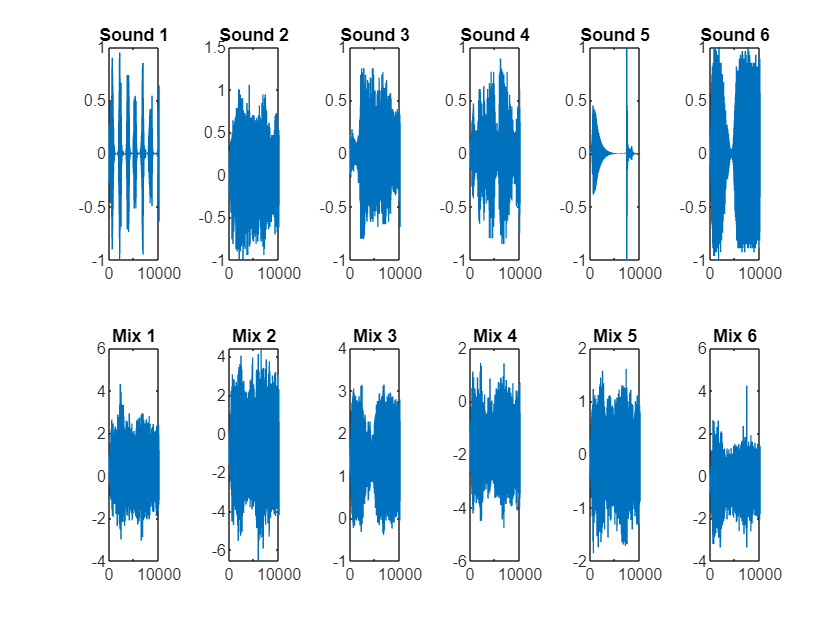

% PLOTs - Original Signals vs Mixed Signals
figure
tiledlayout(2,6)
for i = 1:6
    nexttile(i)
    plot(S(:,i))
    title(['Sound ',num2str(i)])
    nexttile(i+6)
    plot(mixdata(:,i))
    title(['Mix ',num2str(i)])
end

% centering the mixed data
mixdata = mixdata - mean(mixdata);

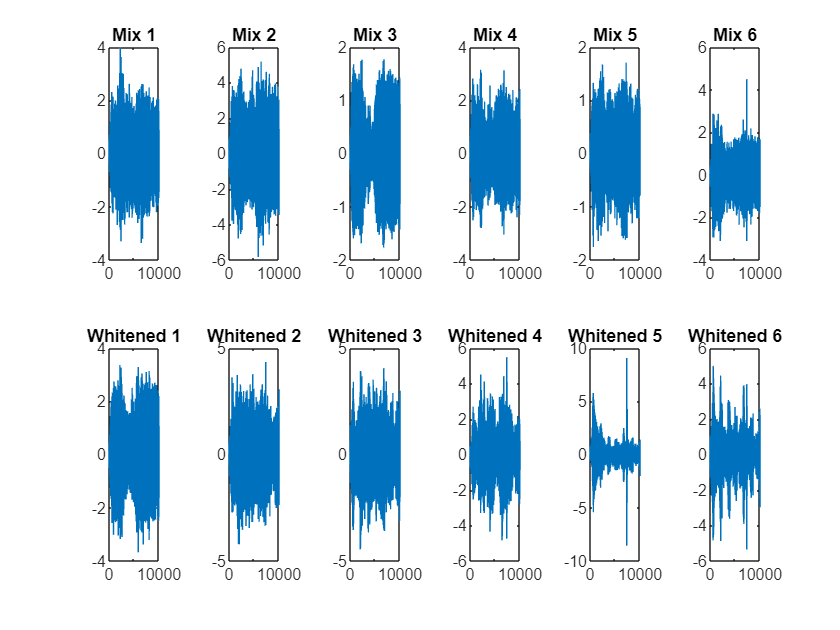

% prewhiten the mixed data
whitened = prewhiten(mixdata);


% PLOTs - Original Mixed Signals vs Whitened Signals
figure
tiledlayout(2,6)
for i = 1:6
    nexttile(i)
    plot(mixdata(:,i))
    title(['Mix ',num2str(i)])
    nexttile(i+6)
    plot(whitened(:,i))
    title(['Whitened ',num2str(i)])
end

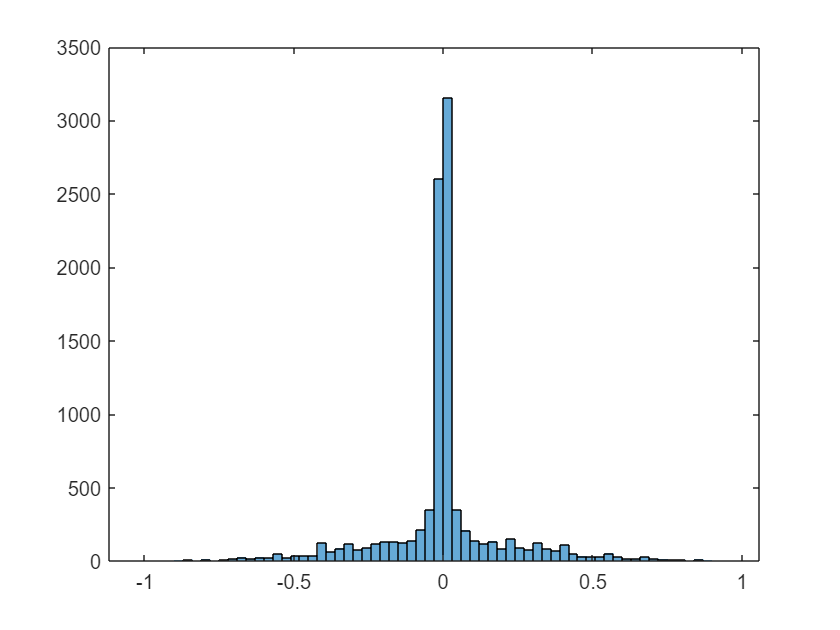

% A super-Gaussian source has a sharp peak near zero,
% such as a histogram of sound 1 shows.
figure
histogram(S(:,1))

% Perform Reconstruction ICA while asking for six features. 
% Indicate that each source is super-Gaussian.
q = 6;
Mdl = rica(whitened,q,'NonGaussianityIndicator',ones(6,1));
Mdl

Mdl =   ReconstructionICA
            ModelParameters: [1×1 struct]
              NumPredictors: 6
         NumLearnedFeatures: 6
                         Mu: []
                      Sigma: []
                    FitInfo: [1×1 struct]
           TransformWeights: [6×6 double]
    InitialTransformWeights: []
    NonGaussianityIndicator: [6×1 double]


  Properties, Methods


% Extract the features
unmixed = transform(Mdl,whitened);

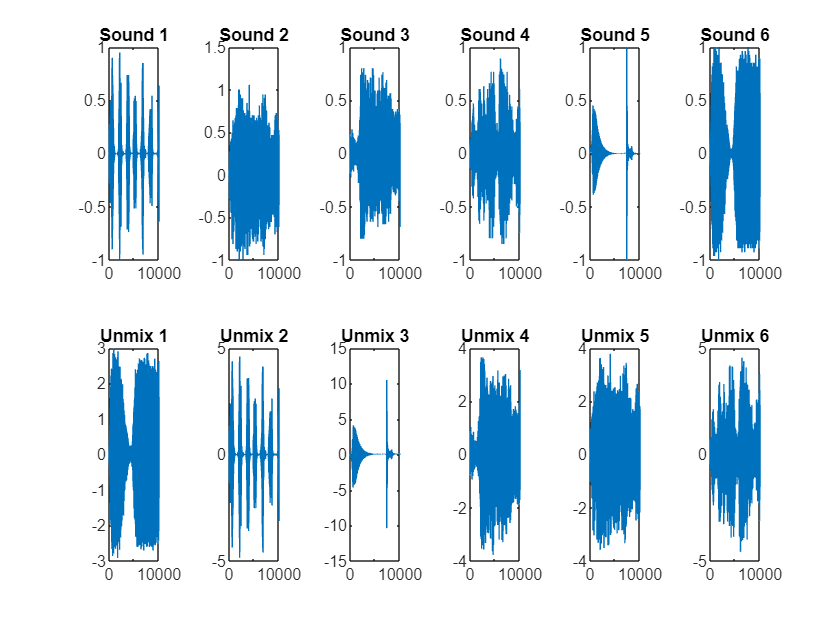


% Plots - Unmixed Signals vs Original Signals
figure
tiledlayout(2,6)
for i = 1:6
    nexttile(i)
    plot(S(:,i))
    title(['Sound ',num2str(i)])
    nexttile(i+6)
    plot(unmixed(:,i))
    title(['Unmix ',num2str(i)])
end

% Reordering the columns to that unmixed signal match corresponding
% origninal signal
unmixed = unmixed(:,[2,5,4,6,3,1]);
for i = 1:6
    unmixed(:,i) = unmixed(:,i)/norm(unmixed(:,i))*norm(S(:,i));
end

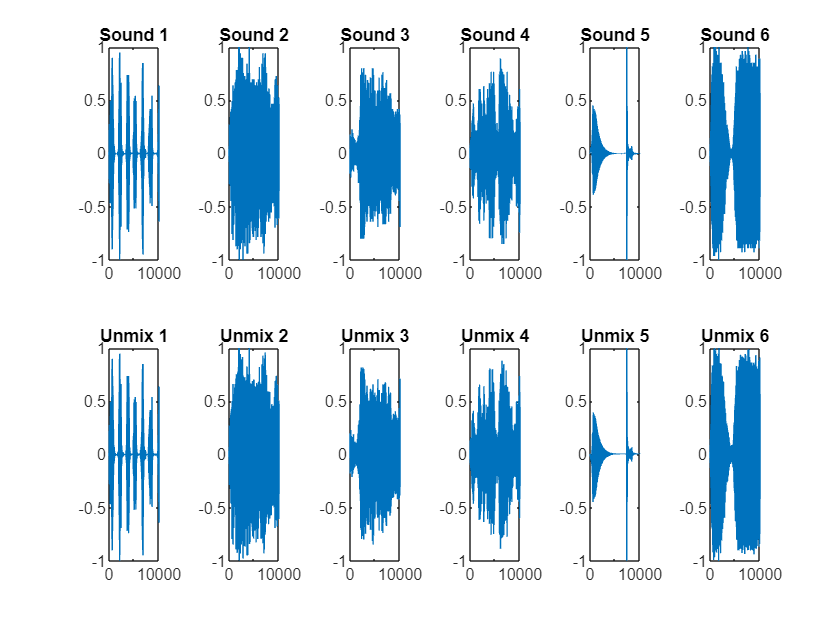

% Plots - Original and Unmixed signals.
figure
tiledlayout(2,6)
for i = 1:6
    nexttile(i)
    plot(S(:,i))
    ylim([-1,1])
    title(['Sound ',num2str(i)])
    nexttile(i+6)
    plot(unmixed(:,i))
    ylim([-1,1])
    title(['Unmix ',num2str(i)])
end

function [X] = whiten(X)
X = bsxfun(@minus, X, mean(X));
A = X'*X;
[V,D] = eig(A);
X = X*V*diag(1./(diag(D)).^(1/2))*V';
end


Prewhiten function

function Z = prewhiten(X)
% X = N-by-P matrix for N observations and P predictors
% Z = N-by-P prewhitened matrix

    % 1. Size of X.
    [N,P] = size(X);
    assert(N >= P);

    % 2. SVD of covariance of X. We could also use svd(X) to proceed but N
    % can be large and so we sacrifice some accuracy for speed.
    [U,Sig] = svd(cov(X));
    Sig     = diag(Sig);
    Sig     = Sig(:)';

    % 3. Figure out which values of Sig are non-zero.
    tol = eps(class(X));
    idx = (Sig > max(Sig)*tol);
    assert(~all(idx == 0));

    % 4. Get the non-zero elements of Sig and corresponding columns of U.
    Sig = Sig(idx);
    U   = U(:,idx);

    % 5. Compute prewhitened data.
    mu = mean(X,1);
    Z = bsxfun(@minus,X,mu);
    Z = bsxfun(@times,Z*U,1./sqrt(Sig));
end